clc;
clear;
syms t
syms theta1(t)  theta2(t) Lr Lp B mp mr Jp Jr g tau ddtheta1 ddtheta2
dtheta1 = diff(theta1, t);
dtheta2 = diff(theta2, t);

Mr_val = 0.095;
Mp_val = 0.024;
Lp_val = 0.129;
Lr_val = 0.085;
Jr_val = 1.4*10^-6+0.6*10^-6;
Jp_val = 1/3*Mp_val*Lp_val^2;
g_val = 9.82;


T_B_1 = [rotz(theta1), [0, 0, 0].'; [0, 0, 0, 1]];
T_1_2 = [rotx(-pi/2)*rotz(pi/2+theta2), [0, Lr, 0].'; [0, 0, 0, 1]];
T_2_p = [eye(3), [Lp/2, 0, 0].'; 0, 0, 0, 1];
T_B_2 = T_B_1*T_1_2;
T_B_p = T_B_2*T_2_p;
 

p_B_2org = T_B_2 * [0, 0, 0, 1].';
p_B_p = T_B_p * [0, 0, 0, 1].';
p_B_p = simplify(p_B_p)

$$p\_B\_p(t) = \left(\begin{array}{c} -\mathrm{Lr}\,\sin\left(\theta_{1}\left(t\right)\right)-\frac{\mathrm{Lp}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)}{2}\\ \mathrm{Lr}\,\cos\left(\theta_{1}\left(t\right)\right)-\frac{\mathrm{Lp}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)}{2}\\ -\frac{\mathrm{Lp}\,\cos\left(\theta_{2}\left(t\right)\right)}{2}\\ 1 \end{array}\right)$$


v_2org = diff(p_B_2org, t);
v_2org = v_2org(t);
v_2org_squared = v_2org(1)^2+v_2org(2)^2+v_2org(3)^2;
v_p = diff(p_B_p, t);
v_p = v_p(t);
v_p_squared = v_p(1)^2+v_p(2)^2+v_p(3)^2;;

J1 = Jr + Lp^2*mp*1/3*sin(theta2)^2+mp*Lr^2;


E_kin = 1/2*(mp*v_p_squared+mr*v_2org_squared) + 1/2 *(Jp*dtheta2^2+J1*dtheta1^2);
E_pot = Lp/2*g*mp*(1-cos(theta2));

L = E_kin - E_pot;
dLdx = simplify([diff(L, theta1(t)); diff(L, theta2(t))]);
dLddx = simplify([diff(L, dtheta1(t)); diff(L, dtheta2(t))]);
ddtdLddx = simplify(diff(dLddx, t));
Q = [tau; 0];

eq = simplify(ddtdLddx-dLdx) == Q;
eq_sub = subs(eq, [diff(theta1, t, 2), diff(theta2, t, 2)], [ddtheta1, ddtheta2]);

sol = solve(eq_sub, [ddtheta1, ddtheta2]);
ddtheta1_sol = simplify(sol.ddtheta1);
ddtheta2_sol = simplify(sol.ddtheta2);

% State vector and nonlinear state equation
x = [theta1(t); theta2(t); dtheta1(t); dtheta2(t)];
dx = [dtheta1(t); dtheta2(t); ddtheta1_sol; ddtheta2_sol];

% Input
u = tau;

% Operating point
x0 = [0; pi; 0; 0];
u0 = 0;

% Jacobians
A = jacobian(dx, x);
B = jacobian(dx, u);

% Evaluate at operating point
A_lin = simplify(subs(A, [x; u], [x0; u0]));
B_lin = simplify(subs(B, [x; u], [x0; u0]));

% Output matrix (example: all states as outputs)
C_lin = [0 1 0 0];
D_lin = 0;


old = [mr, mp, Lp, Lr, Jr, Jp, g];
new = [Mr_val, Mp_val, Lp_val, Lr_val, Jr_val, Jp_val, g_val];

A_lin = subs(A_lin, old, new);
B_lin = subs(B_lin, old, new);
C_lin = subs(C_lin, old, new);
D_lin = subs(D_lin, old, new);

A_num = double(A_lin);
B_num = double(B_lin);
C_num = double(C_lin);
D_num = double(D_lin);


sys = ss(A_num, B_num, C_num, D_num);

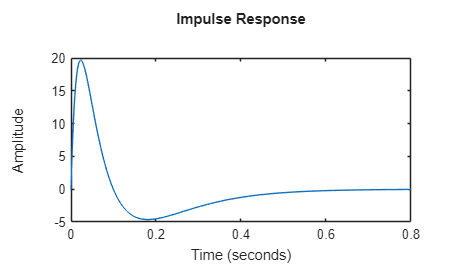

Kp = 10;
Ki = 5;
Kd = 1;

Cpid = pidtune(sys, 'PID');

T_r = feedback(sys,Cpid, -1); 
impulse(T_r*4)